# Tutorial session 2 - Linear Programming

%% initialization data
clear all
close all
clc

## 1) Introduction

The aim of this tutorial is to deal in an optimization framework with a series of problems related to the multi-agent coverage and the geometrical properties of polyhedral sets in a finite dimensional state space. Such constructions appear in robotics, safe and rescue applications, economic/administrative decisions and other related fields. 

All the real-world objectives below need to be translated into an equivalent optimization problems discussed in the Optimization course and solved accordingly.

## 2) Find the point with the largest distance to the boundaries of a polyhedral set

Consider a mobile robot positioned in a constrained environment. This environment will be represented by a convex set with the boundaries given by the following half-space representation:


$$P=\left\lbrace x\in \mathbb{R}²\;\;|\;\;\left\lbrack \begin{array}{cc}
0 & -1\\
-1 & 0\\
3 & -4\\
0 & 1
\end{array}\right\rbrack \;x\le \left\lbrack \begin{array}{c}
0\\
0\\
1\\
1
\end{array}\right\rbrack \;\;\;\;\right\rbrace$$


A mobile robot is positioned at the origin in this set, the wheels are blocked (no possible turning maneuver) and the heading angle allows moves on the line:


$$D=\left\lbrace x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack \;\in \mathbb{R}{\;}^{2\;} |\;\;x_1 =x_2 \right\rbrace$$


The set $P$ and the restriction $D$ are illustrated in Figure 1.a***. ***The first objective is to find the best possible position of the robot within this constrained set in such a way that the minimal distance to the boundaries is maximized. The distance to the boundaries is denoted as **Tchebychev radius**.

A graphical illustration of the ideal configuration is presented in Figure 1.b.

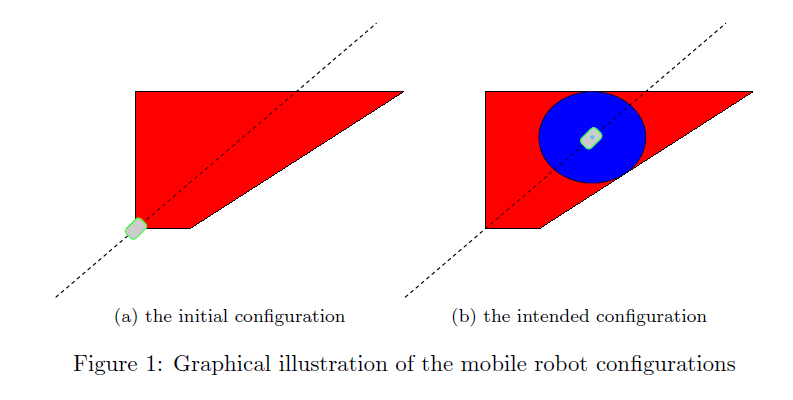

**Question 1** : Follow the next steps in order to provide a numerical solution:

**1.a)** Describe the ball situated at the position $x_c$ and radius $\rho$ (to express as a function of the unit ball)

**1.b)** Write the objective of the design in terms of an optimization of the radius of such a ball

**1.c)** Impose the adequate constraints on the $x_c$ and $\rho$ in order to fulfill the limitations on the positioning of the robot and the distance to the boundaries of the given environment

**1.d)** Show that this is a linear programming problem

**1.e) **Bring the LP to the standard form

**1.f)** Solve the problem by completing the the Matlab script that calls the routine `simplex.m` implementing Dantzig's Simplex method (provided)

%%P
PV=[0 0; 0 1; 1.66 1; 0.33 0]; % Pv are the vertices of the polyhedron P
A=[0 -1; -1 0 ;  3  -4; 0 1]; 
b=[ 0; 0 ; 1; 1];
pgn=polyshape(PV(:,1),PV(:,2));
figure;
plot(pgn);

% normalize the half space representation in such a way that each
% constraint has a norm =1. i.e. the norm of each row of A is equal to 1
for i=1:size(A,1)
    b(i,1)=b(i)/norm(A(i,:));
    A(i,:)=A(i,:)/norm(A(i,:));
end


% create the matrices in view of the LP formulation of the Tchebyshev ball
% construction
% 
%                   max [c*x] 
%                   s.t.  A_bar *x = b_bar 
%


%Canonical form 
A_bar=[]; % TO BE COMPLETED
b_bar=[]; % TO BE COMPLETED
c=[] % TO BE COMPLETED

% use the procedure simplexe.m 
%N.B: Be careful with the outputs of simplexe function!
% "help simplexe" for more details

[~,~,~,X,~]=simplexe(A_bar,b_bar,c);
xc=X(1:2); % this is the center of the Tchebyshev ball
r=X(3); %the Tchebyshev raduis
%%print the solution
fprintf("The center of the Tchebychev ball is xc = [%f,%f] with raduis rho = %f \n",xc(1),xc(2),r);

**1.g)** Plot the results using the provided routine `ellipplot(eye(2),`$\rho^2$`,'b',`$$x_c$$`)` with the arguments $\rho^2$ and $x_c$ found above.

% plot the result
figure;
hold on;
for i=1:size(A,1)
    plot(xc(1)+r*A(i,1),xc(2)+r*A(i,2),'*');
end

ellipplot(eye(2),r^2,'b',xc'); 
plot(pgn);
plot(xc(1),xc(2),"yo");
plot([-0.5:2],[-0.5:2],'k--'); 
axis([-0.2 1.7 -0.2 1.7]);
hold off;

## 3) On the iterations and the structure of the problem

**Question 2**: Solve the problem "by hand" with Dantzig's simplex algorithm specifying the intermediate steps all by discussing the uniqueness and boundedness.

Show that ultimately, there are two optimization arguments. Provide a graphical interpretation for the constraints in a two-dimensional representation by:

- drawing constraints

- identifying the redundant constraints(if any)

- plot the iso-cost profile

- show the iterations of the Dantzig's algorithm on this graphical representation. (To do at home if interested in the Simplex algorithm)

## 4) Two particular cases

Suppose that the limits of the environment are slightly perturbed to:


$$P_1 =\left\lbrace x\in \mathbb{R}²\;\;|\;\;\left\lbrack \begin{array}{cc}
0 & -1\\
-1 & 0\\
4 & -4\\
0 & 1\\
-0\ldotp 5 & 0\ldotp 5
\end{array}\right\rbrack \;x\le \left\lbrack \begin{array}{c}
0\\
0\\
2\\
1\\
0\ldotp 4
\end{array}\right\rbrack \;\;\;\;\right\rbrace$$


**Question 3**: Describe the change in the solution and the uniqueness and boundedness properties.

%%P1
PV=[0 0; 0 0.8; 0.2 1; 1.5 1; 0.5 0];
A=[0 -1; -1 0 ;  4  -4; 0 1;-0.5 0.5];
b=[ 0; 0 ; 2; 1; 0.4];
pgn1=polyshape(PV(:,1),PV(:,2));
figure;
plot(pgn1)

- **Comment:**

**Question 4**: Same question for the constraints:


$$P_2 =\left\lbrace x\in \mathbb{R}²\;\;|\;\;\left\lbrack \begin{array}{cc}
0 & -1\\
-1 & 0\\
3 & -4
\end{array}\right\rbrack \;x\le \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \;\;\;\;\right\rbrace$$


%%P2
PV=[0 0; 0.33 0];
A=[0 -1; -1 0 ;  3  -4];
b=[ 0; 0 ; 1];
%pgn=polyshape(PV(:,1),PV(:,2));
%figure;
%plot(pgn2);

- **Comment:**

## 5) From unidirectional to multidirectional robots

We suppose next that the robot or multiagent system can move in any direction of the 2D space (the constraint: $x_1 = x_2$ is relaxed). 

**Question 5 **: Describe the new optimization problem which allows the construction of the Tchebychev ball in any given bounded polyhedral set in $\mathbb{R}^2$ . Implement and analyze the degrees of freedom and the maximal number of active inequality constraints for the numerical example $x\in P$.

## 6) Multiple robots and their deployment

We will move next from the deployment of one robot in a stationary configuration to the deployment of fleet of robots that share a common environment. In this framework, consider the working space to be described by a box:


$$B=\left\lbrace x\in \mathbb{R}²\;\;|\;\;\left\lbrack \begin{array}{cc}
0 & -1\\
-1 & 0\\
0 & 1\\
1 & 0
\end{array}\right\rbrack \;x\le \left\lbrack \begin{array}{c}
0\\
0\\
5\\
10
\end{array}\right\rbrack \;\;\;\;\right\rbrace$$


Let $5$ agents positioned at the following coordinates at the first time instant:


$$c_1 \left(1\right)=\;\left\lbrack \begin{array}{c}
1\\
2\ldotp 5
\end{array}\right\rbrack \;\;\;;\;\;c_2 \left(1\right)=\;\left\lbrack \begin{array}{c}
4\\
1
\end{array}\right\rbrack \;\;;\;c_3 \left(1\right)=\;\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack \;\;;\;c_4 \left(1\right)=\;\left\lbrack \begin{array}{c}
2\\
4
\end{array}\right\rbrack \;\;;\;c_5 \left(1\right)=\;\left\lbrack \begin{array}{c}
8\\
2\ldotp 5
\end{array}\right\rbrack$$


At time instant $k$, at each of such coordinates at $c_i(k);\quad  i = 1,\dots, 5$ corresponds an associated polyhedral cell defined as:


$$V_i \left(k\right)=\lbrace x\in B\;\;|\;\;2\;{\left(c_j \left(k\right)-c_i \left(k\right)\right)}^{\top \;} x\le \|c_j \left(k\right){\|}^2 -\|c_i \left(k\right)\parallel^2 \;,\forall \;j\not= i\rbrace \;$$


The partition of the given box in according to this disjoint union of cells is also called Voronoi partition.

**Question 6**: Compute the Tchebychev center of each of those cells $x_{c_i}(k); \quad i = 1,\dots,5$  and simulate for $20$ iterations the dynamics:

 
$$c_i(k+1)=x_{c_i}(k)$$


and verify the convergence towards the configuration in Figure 2.b.

%%
clear all
%we define first the boundaries of the environement
BV=[0 0; 0 5;  10 5; 10 0];
B_A=[   0   -1; 1   0;   0    1;   -1.0000    0.0000];
B_b=[   0  ; 10; 5; 0];

Bpgn=polyshape(BV(:,1),BV(:,2));
plot(Bpgn)

%then provide the initial positions of the agents
c{1}=[1;2.5];c{2}=[4;1];c{3}=[2;1];c{4}=[2;4];c{5}=[8;2.5];
%c{1}=[1;2];c{2}=[1;3];c{3}=[2;1];c{4}=[2;4];c{5}=[8;2.5];
%%
% for each time step t, and for each agent i, we create the polyhedral
% domain V_i(t)
ck=cell(5,20); rk=cell(5,20);
for t=1:20
for i=1:5
    A=[]; b=[]; % TO BE COMPLETED
    for j=1:5
        if j~=i
            A=[]; % TO BE COMPLETED
            b=[]; % TO BE COMPLETED
        end
    end
    V_A{i}=A;
    V_b{i}=b;
end

% create the matrices in view of the LP formulation of the Chebyshev ball
% construction
% 
%                   max f'*x 
%                   s.t.  A_bar *x <= b_bar 
%
for i=1:5
    %radius of the Chebyshev ball is positive
    A_bar= []; % TO BE COMPLETED
    b_bar=[]; % TO BE COMPLETED
    
    
    % the objective function f'*x
    f=[]; % TO BE COMPLETED
    
    %solve the LP 
    X = linprog(f,A_bar,b_bar)
    
    %extract the optimal values
    xc{i}=X(1:2); % this is the center of the Chebyshev radius
    rc{i}=X(3); %the Chebyshev radius
    

end

for i=1:5
    ck{i,t}=xc{i}; c{i}=xc{i};
    rk{i,t}= rc{i};
end

end

%plot
figure
hold on
plot(Bpgn);

for i=1:5
ellipplot(eye(2),rk{i,1}^2,'b',ck{i,1})
% hold on
plot(ck{i,1}(1),ck{i,1}(2),'*')
end

for i=1:5
ellipplot(eye(2),rk{i,20}^2,'r',ck{i,20})
% hold on
plot(ck{i,20}(1),ck{i,20}(2),'*r')
end
%%
figure
for t=1:20
for i=1:5
ellipplot(eye(2),rk{i,t}^2,'b',ck{i,t})
 hold on
plot(ck{i,t}(1),ck{i,t}(2),'*')
end
hold off
pause(0.1)
end